Comparing the accuracy of pca for different values of k

The weights for a person is the average of the weights for all photos of that person

Creating the train and test file

accuracy = zeros([15, 1]);
for k = 10:10:150
    load YaleB_32x32.mat
    %accuracy = 0;
    num_of_passes = 0;
    for iter=0:10    
        [data_size,image_size] = size(fea);
        image_size = sqrt(image_size);
        test_index = randi(data_size,1,100);
        train_index = 1:data_size;
        train_index(test_index) = [];
        
        train_face = fea(train_index,:)';
        train_label = gnd(train_index,:);
        test_face = fea(test_index,:)';
        test_label = gnd(test_index,:);
        train_size = size(train_index,2);
        test_size = size(test_index,2);

Mean

        train_mean = mean(train_face,2);
        train_face = train_face - train_mean;

Eigen-faces

        [eigen_faces,eigen_value,~] = svd(train_face'*train_face);
        eigen_faces = normc(train_face*eigen_faces);
        eigen_faces = eigen_faces(:,4:k+3); 
        eigen_value = diag(eigen_value);
        eigen_value = eigen_value(4:k+3)';

Projection

        weights = eigen_faces' * train_face;
        train_weights = zeros([k,train_size]);
        num_faces = zeros([1,train_size]);
        for i = 1:train_size
            num_faces(1,train_label(i)) =  num_faces(1,train_label(i)) +1;
            train_weights(:,train_label(i)) = train_weights(:,train_label(i)) + (weights(:,i) - train_weights(:,train_label(i)))/num_faces(1,train_label(i));
        end

Check

        reduce = eigen_faces * train_weights;
        %imagesc(reshape(train_mean+train_face(:,1),[64 64]))
        %imagesc(reshape(train_face(:,1),[64 64]))
        %imagesc(reshape(train_mean+reduce(:,1),[32 32]))
        %imagesc(reshape(reduce(:,1),[64 64]))

Test

        test_weights = eigen_faces'*(test_face - train_mean);
        test_reduce = eigen_faces*test_weights;
        acc = test_size;
        for i = 1:test_size
            test = test_weights(:,i);
            no = vecnorm(train_weights - test);
            [M, I] = min(no);
            if I ~= test_label(i)
                acc=acc-1;
                %disp([test_label(i), I])
                %figure
                %imagesc(reshape(reduce(:,I), [32 ,32]))
                %figure
                %imagesc(reshape(test_reduce(:,i), [32 ,32]))
            end
        end
        acc = acc*100/test_size;
        num_of_passes = num_of_passes+1;
        accuracy(k/10) = accuracy(k/10)+(acc-accuracy(k/10))/num_of_passes;
        %disp([acc , accuracy(k/10)])
    end
    disp([k , accuracy(k/10)]);
end

   10.0000   35.8182

   20.0000   54.3636

   30.0000   57.3636

   40.0000   61.6364

   50.0000   65.2727

   60.0000   59.6364

   70.0000   63.0909

   80.0000   69.1818

   90.0000   67.4545

  100.0000   66.3636

  110.0000   68.7273

  120.0000   65.5455

  130.0000   68.0000

  140.0000   65.6364

  150.0000   66.9091



Plotting the accuracy

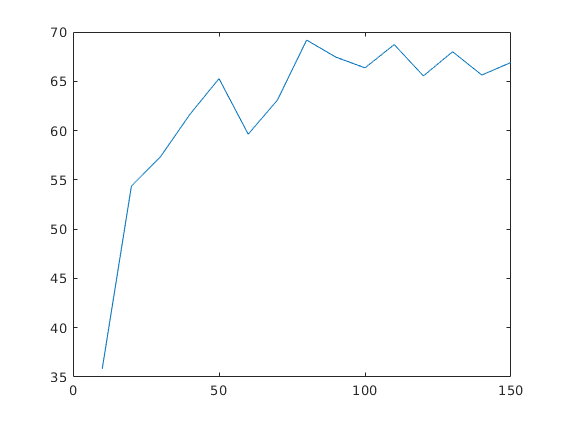

plot(10:10:150, accuracy)